**Laboratorium 7 – ** **Dyskretna transformacja Fouriera**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

1.1 Ćwiczenie 1

clear all; close all
syms t w

N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.2616e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.2616e-13



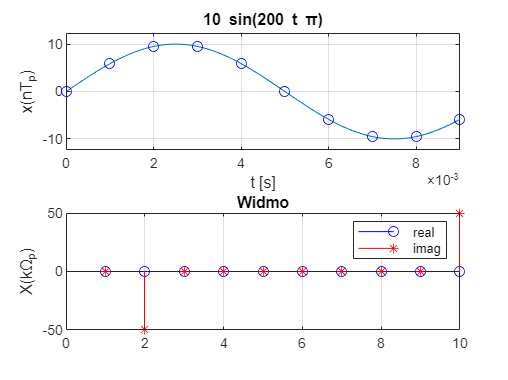


figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

1.2 Zadanie 2

Powyższy kod wyświetla numery próbek, zamiast konkretnych częstotliwości, stąd należy wykonać następujące poprawki:

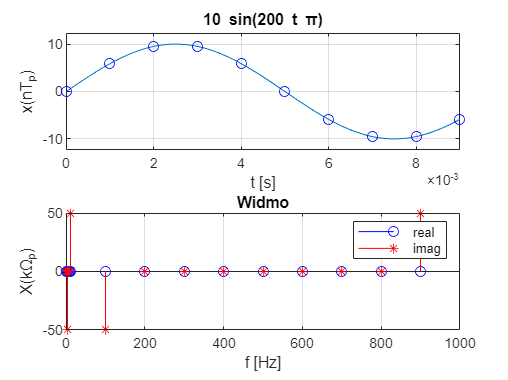

wk = fp*[0:N-1]/N; % oś częstotliwości
% należy przekazać funkcji stem() wartości na osi X
stem(wk, real(Xk), 'ob'); grid on; hold on;
stem(wk, imag(Xk), '*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

1.3 Zadanie 3

W DFT jedynie dolna połowa widma jest użyteczna (jego lewa część), czyli próbki od 0 do N/2. Pozostałe próbki należy więc odrzucić:

wk = fp*[0:N/2-1]/N; % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); xlabel('f [Hz]')
legend('real','imag')

1.4 Zadanie 4

Została zaimplementowana wizualizacja gęstości widmowej amplitudy oraz fazy w następujący sposób:

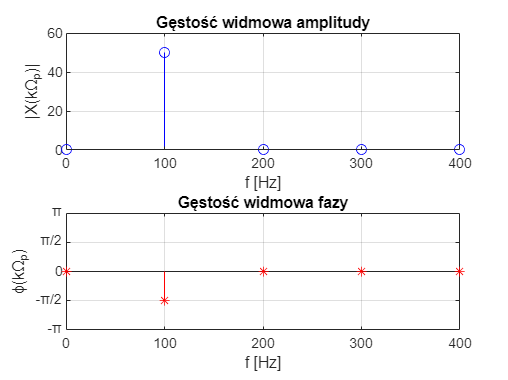

tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2);
subplot(2,1,1);
wk = fp*[0:N/2-1]/N; 
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');

subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

1.5 Zadanie 5

W powyższych przykładach liczba próbek wynosiła N = 10. 

Teraz zastosujemy wyższą liczbę próbek: N = 15 i N = 20. Zaczniemy od N = 15:

clear all; close all
syms t w

N = 15; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 

fk = zeros(1,N);
for k = 0:N-1
    fk(k+1) = fp*k/N;
end

Xk_1 = Xk(1:(N/2+1));

fk_1 = fk(1:(N/2+1));

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 6.7921e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   6.7921e-13



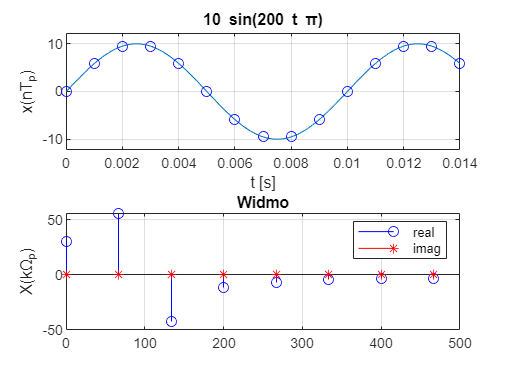


figure(1);

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(fk_1, real(Xk_1),'ob'); grid on, hold on
stem(fk_1, imag(Xk_1),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')



tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2); 
subplot(2,1,1); 
wk = fp*[0:N/2-1]/N; 
stem(wk, abs(Xk(1:N/2)), 'ob'); 

grid on; hold on; 
ylabel('|X(k\Omega_p)|'); 
title('Gęstość widmowa amplitudy'); 
xlabel('f [Hz]');


subplot(2,1,2); 

stem(wk, angle(Xk(1:N/2)), '*r'); 

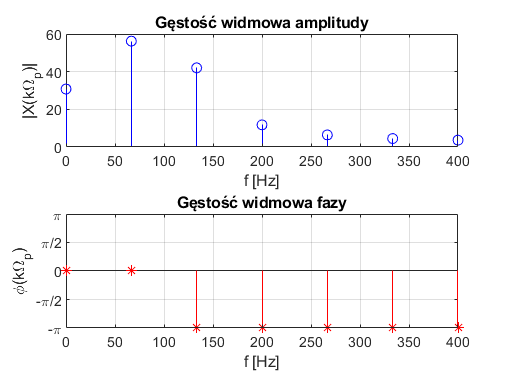

grid on; 
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');

Następnie zmieniono liczbę próbek na  N = 20:

clear all; close all
syms t w

N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 

fk = zeros(1,N);
for k = 0:N-1
    fk(k+1) = fp*k/N;
end

Xk_1 = Xk(1:(N/2+1));
fk_1 = fk(1:(N/2+1));
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 9.5509e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   9.5509e-13



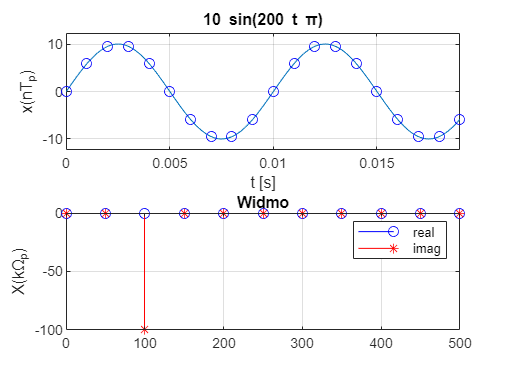


figure(1);

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(fk_1, real(Xk_1),'ob'); grid on, hold on
stem(fk_1, imag(Xk_1),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

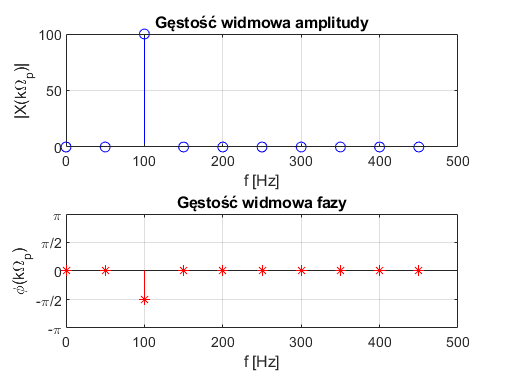



tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2); 
subplot(2,1,1); 
wk = fp*[0:N/2-1]/N; 
stem(wk, abs(Xk(1:N/2)), 'ob'); 
grid on; hold on; 
ylabel('|X(k\Omega_p)|'); 
title('Gęstość widmowa amplitudy'); 
xlabel('f [Hz]');


subplot(2,1,2); 

stem(wk, angle(Xk(1:N/2)), '*r'); 
grid on; 
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');

Można zauważyć, że przy dwukrotnym zwiększeniu liczby próbek, moc sygnału również wzrosła dwukrotnie, natomiast faza nie zmieniła się.

Dla N = 15 , jako że nie ma próbki odpowiadającej dokładnie częstotliwości sygnału (100Hz), energia została rozłożona na inne próbki. Wykres gęstości widmowej amplitudy obrazuje pojawienie się składowej stałej.

1.6 Zadanie 6

Liczbę próbek ustawiono na N = 10. Wyznaczono widmo dla sygnału 𝑥3(𝑡)=sin (2𝜋𝑓3𝑡) o częstotliwości 𝑓3=150𝐻𝑧.

clear all; close all
syms t w

N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
x1 = sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.0934e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   1.0934e-14



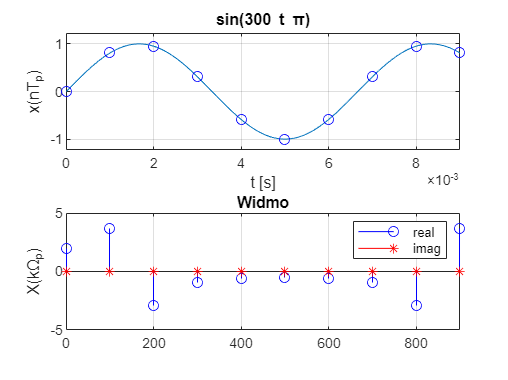


figure;

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(wk, real(Xk),'ob'); grid on, hold on
stem(wk, imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
axis([0 900 -5 5])
legend('real','imag')

Podobnie jak w ostatnim przypadku ćwiczenia poprzedniego, nie ma próbki odpowiadającej bezpośrednio częstotliwości sygnału, stąd energia rozłożyła się na pozostałe próbki. Zjawisko to nazywa się przeciekiem widma.

Zadanie 1.7

Z przeciekiem widma można walczyć, stosując okna. Zostanie porównany wynik działania 3 okien:

a) Okna Trójkątnego

b) Okna Gaussa

c) Okna Czebyszewa

Podpunkt a)

clear all; close all
syms t w ok

N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

ok = triang(N);

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*ok'; 

fk = fp*[0:N/2-1]/N;

Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 


Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 5.0804e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   5.0804e-14



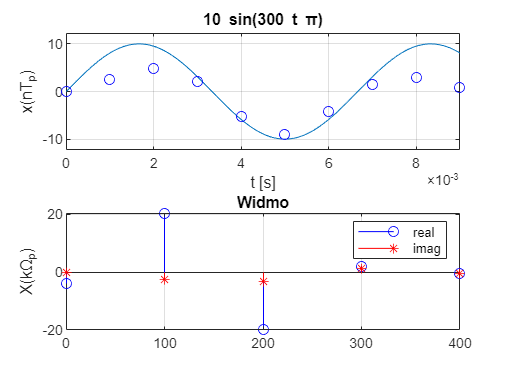


figure;

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(fk, real(Xk(1:N/2)),'ob'); grid on, hold on
stem(fk, imag(Xk(1:N/2)),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

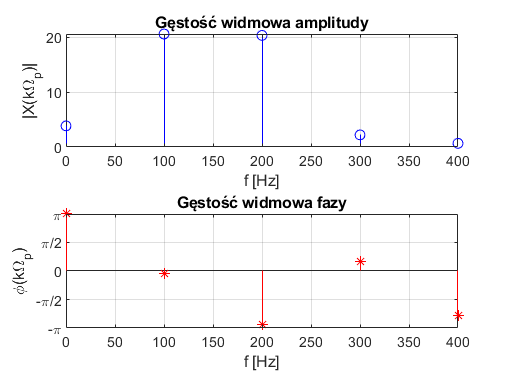



tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2); 
subplot(2,1,1); 
stem(fk, abs(Xk(1:N/2)), 'ob'); 
grid on; hold on; 
ylabel('|X(k\Omega_p)|'); 
title('Gęstość widmowa amplitudy'); 
xlabel('f [Hz]');


subplot(2,1,2); 

stem(fk, angle(Xk(1:N/2)), '*r'); 
grid on; 
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');

Podpunkt b)

clear all; close all
syms t w ok

N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

ok = window(@gausswin,N,2.5);

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*window(@gausswin,N,2.5)'; 

fk = fp*[0:N/2-1]/N;

Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 


Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 5.7182e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   5.7182e-14



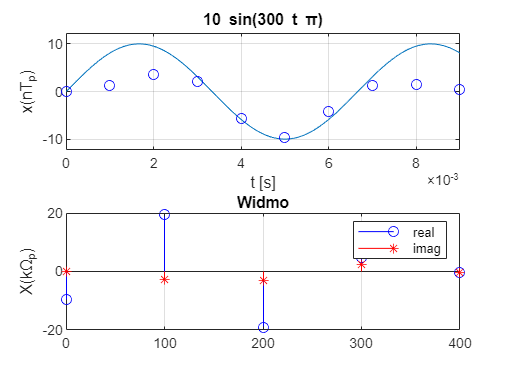


figure;

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(fk, real(Xk(1:N/2)),'ob'); grid on, hold on
stem(fk, imag(Xk(1:N/2)),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

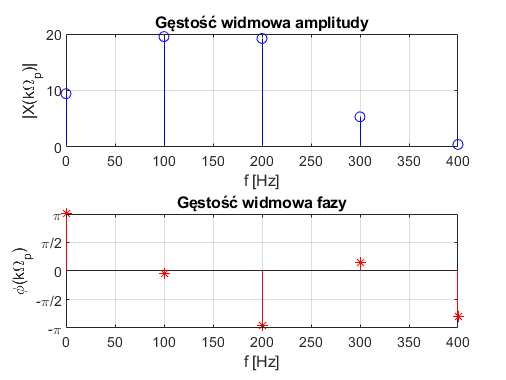



tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2); 
subplot(2,1,1); 
stem(fk, abs(Xk(1:N/2)), 'ob'); 
grid on; hold on; 
ylabel('|X(k\Omega_p)|'); 
title('Gęstość widmowa amplitudy'); 
xlabel('f [Hz]');


subplot(2,1,2); 

stem(fk, angle(Xk(1:N/2)), '*r'); 
grid on; 
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');

Podpunkt c)

clear all; close all
syms t w ok

N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 150; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

ok = chebwin(N);

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*chebwin(N)';

fk = fp*[0:N/2-1]/N;

Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 


Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 5.7886e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   5.7886e-14



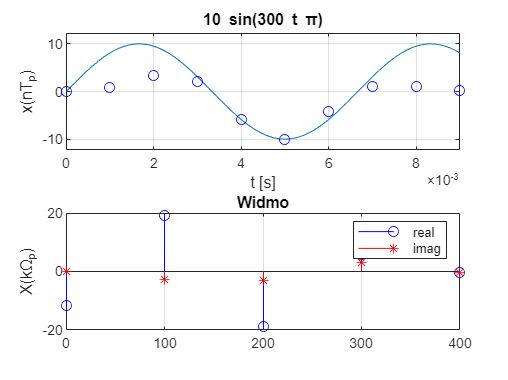


figure;

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(fk, real(Xk(1:N/2)),'ob'); grid on, hold on
stem(fk, imag(Xk(1:N/2)),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

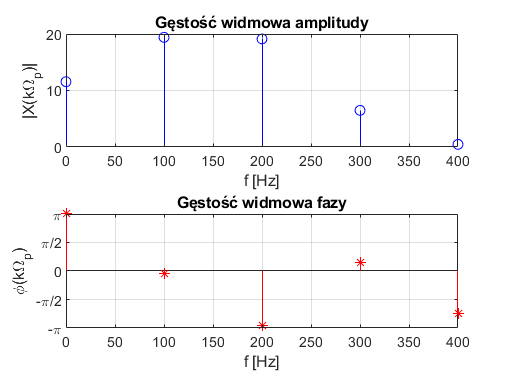



tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2); 
subplot(2,1,1); 
stem(fk, abs(Xk(1:N/2)), 'ob'); 
grid on; hold on; 
ylabel('|X(k\Omega_p)|'); 
title('Gęstość widmowa amplitudy'); 
xlabel('f [Hz]');


subplot(2,1,2); 

stem(fk, angle(Xk(1:N/2)), '*r'); 
grid on; 
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');

Najlepsze efekty dało zastosowanie okna trójkątnego. Dla sygnału o częstotliwości 150Hz po jego zastosowaniu, największą amplitudę miały próbki odpowiadające najbliżej leżącym częstotliwościom, tj. 100Hz i 200Hz. Pozostałe zostały znacznie zmniejszone. Okna Gaussa i Czebyszewa zadziałały podobnie, w obu jednak pojawiła się dość duża składowa stała, okna w ogóle jej nie odfiltrowały.

Zadanie 1.8

clear all; close all
syms t w

N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A2 = 5;
A1 = 10; f1 = 150; %Hz\
f1 = 100

f1 = 100

f2 = 200;
x1 = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);
x = x1;



tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
fk = fp*[0:N/2-1]/N;
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end 


Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.5487e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.5487e-13



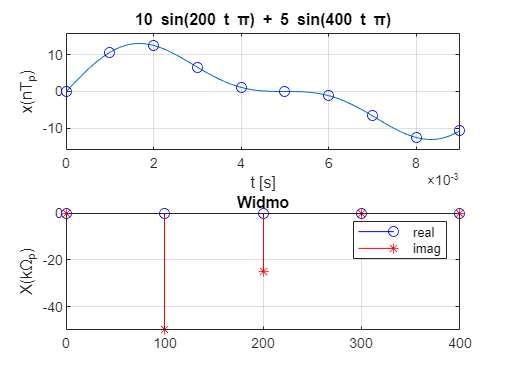


figure;

subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); 
ylabel('x(nT_p)');

subplot(2,1,2)
wk = fp*[0:N-1]/N;   % skalowanie
stem(fk, real(Xk(1:N/2)),'ob'); grid on, hold on
stem(fk, imag(Xk(1:N/2)),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

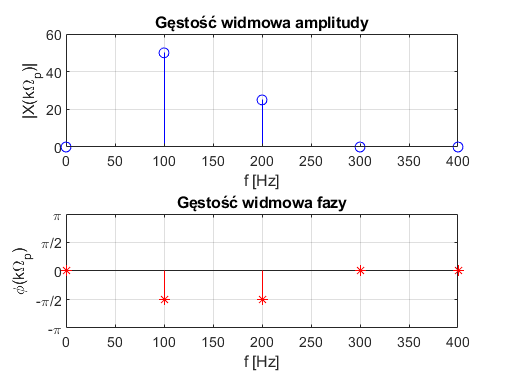



tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(2); 
subplot(2,1,1); 
stem(fk, abs(Xk(1:N/2)), 'ob'); 
grid on; hold on; 
ylabel('|X(k\Omega_p)|'); 
title('Gęstość widmowa amplitudy'); 
xlabel('f [Hz]');


subplot(2,1,2); 

stem(fk, angle(Xk(1:N/2)), '*r'); 
grid on; 
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');

Następnie napisałem następującą funkcję w pliku typu .m, aby nie powtarzać zbędnie kilka razy tego samego kodu, ponieważ w zadaniu wystarczy zmieniać tylko zmienną m:

%function zadanie8(m)
%
%syms t w
%N = 10; % liczba próbek
%fp = 1000;%Hz
%Tp = 1/fp;
%A1 = 10;
%f1 = 100; %Hz
%A2 = 5;
%f2 = 200; %Hz
%x1 = A1*sin(2*pi*f1*t)+A2*sin(2*pi*f2*t);
%x = x1;
%tn = [0:N-1]*Tp; % wsp. czasowe próbek
%xn = double(subs(x,t,tn));
%xn = [xn(end-m+1:end), xn(1:end-m)];
%Xk = zeros(1,N);
%wk = fp*[0:N/2-1]/N;
%for k = 0:N-1 % impl. wzoru (8)
% for n = 0:N-1
% Xk(k+1) = Xk(k+1)+xn(n+1)*exp((-2*pi*1i*k*n)/N);
% end
%end
%Xk_fft = fft(xn,N); %funkcja wbudowana
%dft_err = sum(abs(Xk_fft-Xk));
%disp('DFT error:'); disp(dft_err);
%
%Xk_1 = Xk(1:(N/2));
%tol = 10e-5;
%Xk_1(abs(Xk_1)<tol) = 0;
%g_widm_amp = abs(Xk_1);
%g_widm_faz = (180/pi)*angle(Xk_1);
%figure;
%subplot(2,1,1)
%ezplot(x,[tn(1),tn(N)]); hold on; grid on
%plot(tn, xn,'ob');
%xlabel('t [s]'); ylabel('x(nT_p)');
%subplot(2,1,2)
%stem(wk, real(Xk_1),'ob'); grid on, hold on
%stem(wk, imag(Xk_1),'*r');
%title('Widmo'),
%ylabel('X(k\Omega_p)'); %
%figure;
%subplot(2,1,1)
%stem(wk, g_widm_amp)
%title('Widmowa gęstość amplitudy')
%xlabel('f[Hz]')
%subplot(2,1,2)
%stem(wk, g_widm_faz)
%title('Widmowa gęstęść fazy')
%xlabel('F[Hz)')
%end

Następnie wywołałem tą funkcję:

DFT error:
   1.1547e-13



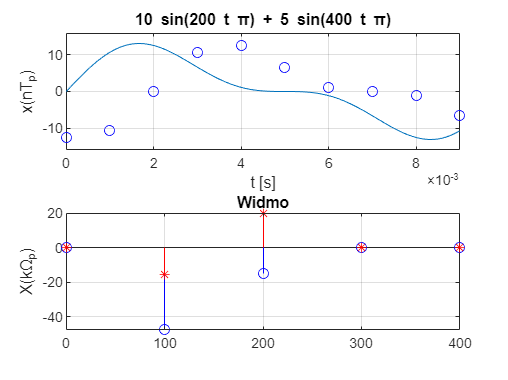

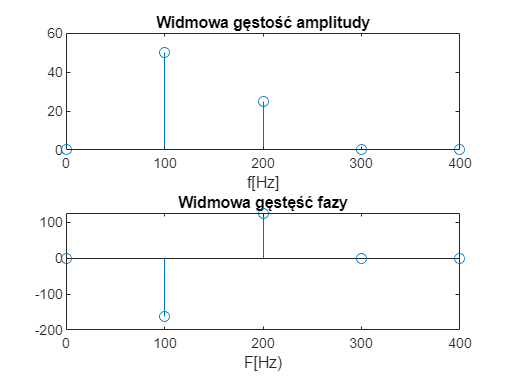

zadanie8(2)

DFT error:
   8.5846e-14



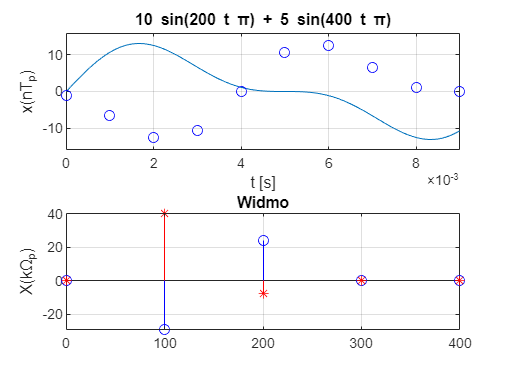

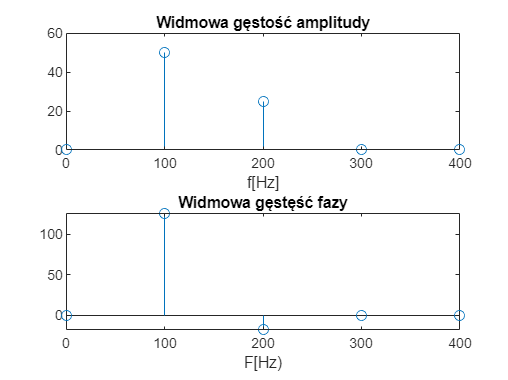

zadanie8(4)

DFT error:
   1.9146e-13



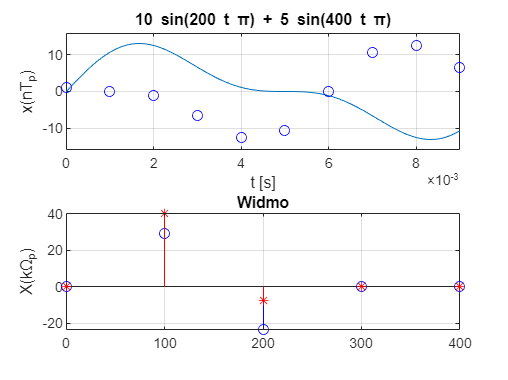

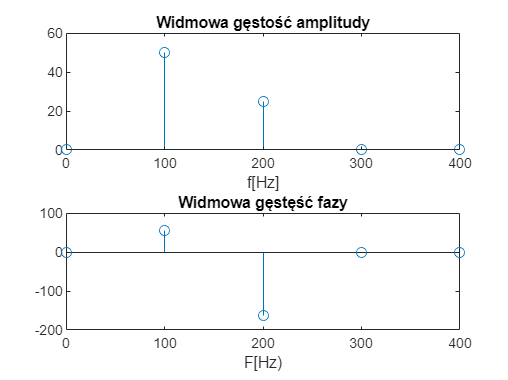

zadanie8(6)

DFT error:
   2.0706e-13



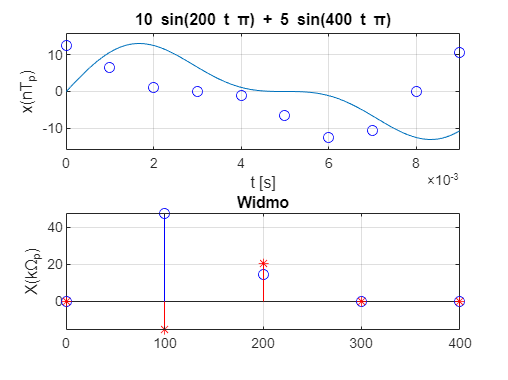

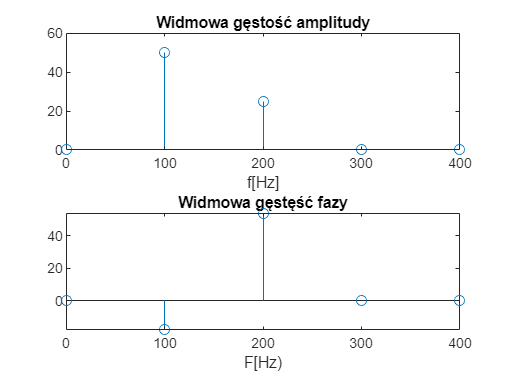

zadanie8(8)

Przy przesunięciu cyklicznym, gęstość widmowa amplitudy pozostaje stała, zmienia się natomiast faza sygnału.

Zadanie Domowe 1.9

Zastąpienie iteracyjnej implementacji dyskretnej transformacji Fourieria realizacją macierzową (przy użyciu wbudowanej funkcji dftmtx tworzącej macierz dyskretnej transformacji Fouriera)

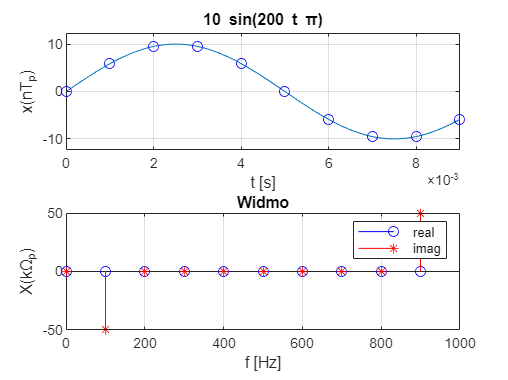

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A1 = 10; 
f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn)); 
Xk = zeros(1,N);

% impl. nowego kodu przy użyciu wbudowanej funkcji Matlaba 
W = dftmtx(N); 
Xk = xn*W;

wp = zeros(1,N);
for i = 0:N-1
    wp(i+1) = fp *i/N;
end

figure(1); 
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob'); 
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2) 
stem(wp, real(Xk),'ob'); grid on, hold on
stem(wp, imag(Xk),'*r'); 
title('Widmo'),
ylabel('X(k\Omega_p)'); xlabel('f [Hz]') 
legend('real','imag')

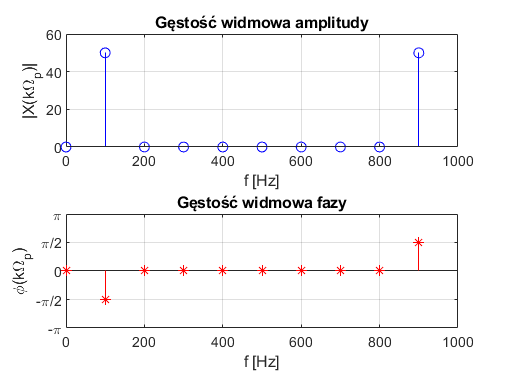


tol = 10e-5; 
Xk( abs(Xk) < tol ) = 0;
figure(2) 
subplot(2,1,1) 
stem(wp, abs(Xk), 'ob'); grid on; hold on;
title('Gęstość widmowa amplitudy'); 
ylabel('|X(k\Omega_p)|'); xlabel('f [Hz]');

subplot(2,1,2) 
stem(wp, angle(Xk), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]); 
ylim([-pi, pi]); 
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'}) 
ylabel('\phi(k\Omega_p)'); 
title('Gęstość widmowa fazy'); 
xlabel('f [Hz]');